# Getting Started with `batch`

You can use batch jobs to offload the execution of long-running computations in the background and carry out other tasks while the batch job is processing. `batch` does not block MATLAB; allowing you to continue working while computations take place in the background. When you submit batch jobs to another computer or cluster, you can close MATLAB on the client and retrieve results later.

In this exercise, you will submit batch jobs from MATLAB to your local machine. The workers will run on the same machine as the client, but the same workflow can be used to submit jobs to a remote compute cluster or the cloud, freeing up your local resources.

*Note*: Close parallel pool if it's open.

## Run a batch job to offload serial computation

`ex_serial` performs, serially, `N` trials of computing the largest eigenvalue for an `M-by-M` random matrix.  `ex_serial` is called as such

% matrix size: 50
% trials: 10000
result = ex_serial(50,10000);

t =           5.05


[batch](https://www.mathworks.com/help/releases/R2018b/distcomp/batch.html?searchHighlight=batch&s_tid=doc_srchtitle) runs your code on a local worker or a cluster worker, but does not require an interactive parallel pool to be running. Use `batch` to offload `ex_serial` onto one MATLAB worker, which is run in the background. 

numOutputs = 1;
sz = 50;
trials = 10000;

% TODO: Submit a serial batch job to run "ex_serial"
job1 = batch(@ex_serial,numOutputs,{sz,trials});

## Job Monitor

You can check the status of your job using the Job Monitor. The Job Monitor displays all the jobs that exist for the cluster specified in the selected profile. Open the Job Monitor from the **Home** tab, then in the **Environment** section select **Parallel** > **Monitor Jobs**.

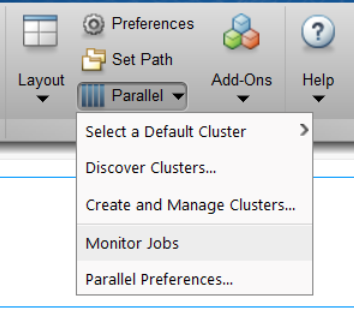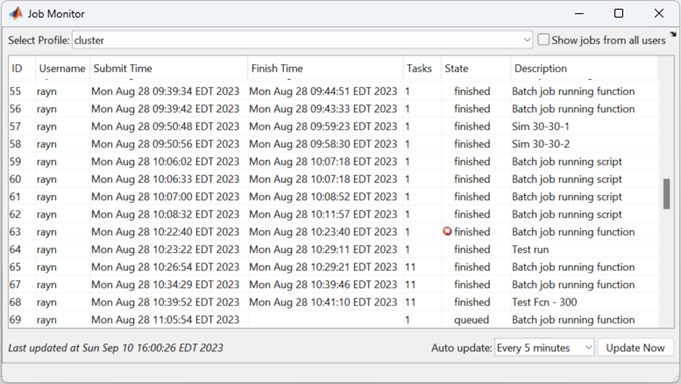

What is the state of your job?

Using the Job Monitor you can manage the listed jobs for your cluster. Right-click on any job in the list, and select any of the following options from the context menu. The available options depend on the type of job.

- **Cancel** — Stops a running job and changes its state to `'finished'`. If the job is pending or queued, the state changes to `'finished'` without it ever running. This is the same as the command-line [`cancel`](https://www.mathworks.com/help/parallel-computing/parallel.task.cancel.html) function for the job.

- **Delete** — Deletes the job data and removes the job from the queue. This is the same as the command-line [`delete`](https://www.mathworks.com/help/parallel-computing/parallel.job.delete.html) function for the job. Also closes and deletes an interactive pool job.

- **Show Details** — Displays detailed information about the job in the Command Window.

- **Show Errors** — Displays all the tasks that generated an error in that job, with their error properties.

- **Fetch Outputs** — Collects all the task output arguments from the job into the client workspace.

When the job completes, fetch the results.

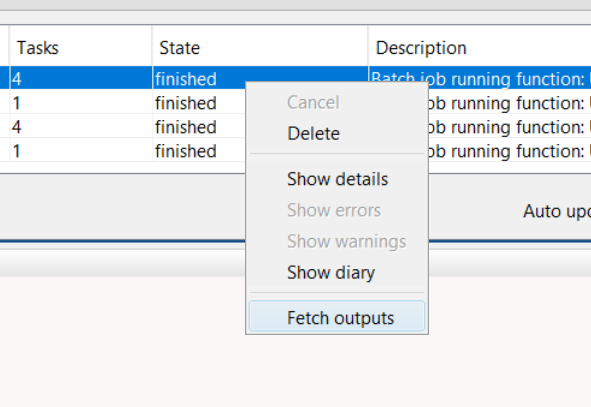

## Offload parallel computation

You can combine the abilities to offload a job and run a for-loop in a parallel pool. Use `batch` to offload the function `ex_parallel`. 

`ex_parallel` performs `N` trials of computing the largest eigenvalue for an `M-by-M` random matrix and runs in parallel  Specify the size of the parallel pool (`numWorkers`) as an additional argument when calling batch,  `numWorkers` are used to iteratate through the for-loop.

numOutputs = 1;
input1 = 50;
trials = 10000;
numWorkers = 2;

% TODO: Submit a parallel batch job to run "ex_parallel"
job2 = batch(@ex_parallel,numOutputs,{input1,trials},'Pool',numWorkers);

How many workers are used and how many running MATLAB instances are there?

*Hint*: The total number of workers will be one more than the size of the pool. Why?

Besides the `numWorkers` used to iterate through the parfor-loop, an additional worker runs the serial code. Thus, `numWorkers`+1 workers are used and there are `numWorkers`+2 total MATLAB instances running.

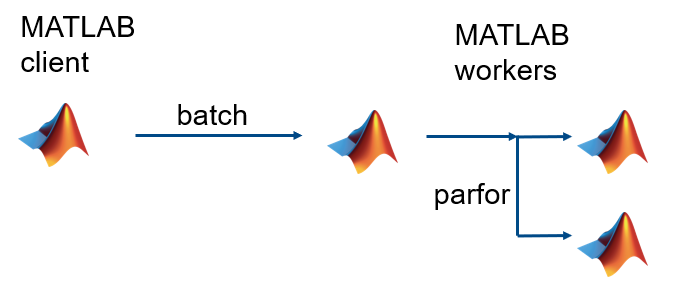

#### Query the state of `job2`

% TODO: Query the state of the parallel job (job2) programatically

job2.State

ans = 'queued'

#### Wait for `job2` to finish

Wait for the parallel job to complete programmatically.

*Hint*: Take a look at the [wait](https://www.mathworks.com/help/parallel-computing/parallel.job.wait.html) method.

% TODO: Wait for the parallel job (job2) to complete programmatically

wait(job2);

Now query the state of the job

job2.State

ans = 'finished'

#### Get results back to the client

Retrieve the parallel job results programmatically.

% TODO: Retrieve the parallel job (job2) results programmatically.  Assign
% it to 'results2'.

results2 = fetchOutputs(job2)

results2 = 1×1 cell array
    {10000×1 double}


## Clean up

When you have loaded all the required variables, delete the job object programmatically to clean up its data and avoid consuming resources unnecessarily. 

*Hint*: Look at the [delete](https://www.mathworks.com/help/parallel-computing/parallel.job.delete.html) method

% TODO: Delete the parallel job (job2) programmatically

delete(job2)

% Turn off Code Analyzer warnings
%#ok<*NASGU>

*Copyright 2024 The MathWorks, Inc.*